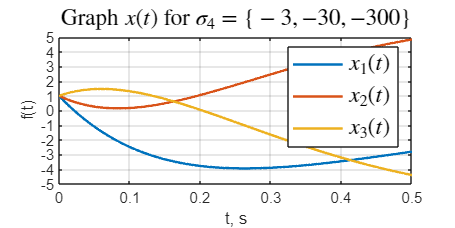

open_system('task_1_sim');
set_param('task_1_sim/x', 'VariableName', 'x')
set_param('task_1_sim/x1', 'VariableName', 'x1')
set_param('task_1_sim/x2', 'VariableName', 'x2')
set_param('task_1_sim/u', 'VariableName', 'u')
set_param('task_1_sim/u1', 'VariableName', 'u1')
set_param('task_1_sim/u2', 'VariableName', 'u2')

out = sim('task_1_sim');

figure('Position', [100 100 800 400])
plot(out.x,'-', 'LineWidth',1.5)
%hold on
%plot(out.y2,'--', 'LineWidth',1.5)
%plot(out.y3,'-.', 'LineWidth',1.5)

grid()
title('Graph $x(t)$ for $\sigma_4 = \{ -3, -30, -300 \}$','Interpreter','latex',  'FontSize', 14)
legend('$x_1(t)$', '$x_2(t)$', '$x_3(t)$', 'Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, s')
yticks([-6 -5 -4 -3 -2 -1 0 1 2 3 4 5 6])

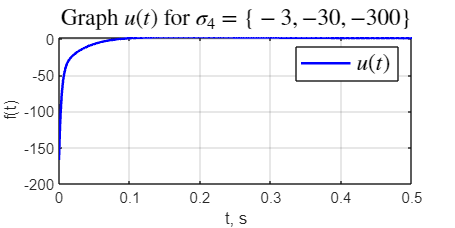

%hold off

plot(out.u1,'b', 'LineWidth', 1.5)
%hold on
%plot(t, y,'b--', 'LineWidth', 1.5)

grid("on")
title('Graph $u(t)$ for $\sigma_4 = \{ -3, -30, -300 \}$', 'Interpreter','latex',  'FontSize', 14)
legend('$u(t)$','Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, s')

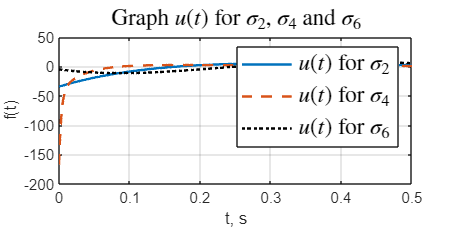

%ylim([-200 100])
%hold off

% для наглядности все графики u(t) на одной плоскости

plot(out.u, 'LineWidth', 1.5)
hold on
plot(out.u1,'--', 'LineWidth', 1.5)
plot(out.u2,'k:', 'LineWidth', 1.5)
%plot(t, y,'b--', 'LineWidth', 1.5)

grid("on")
title('Graph $u(t)$ for $\sigma_2$, $\sigma_4$ and $\sigma_6$', 'Interpreter','latex',  'FontSize', 14)
legend('$u(t)$ for $\sigma_2$', '$u(t)$ for $\sigma_4$', '$u(t)$ for $\sigma_6$','Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, s')
hold off